close all;
clear all;
clc;

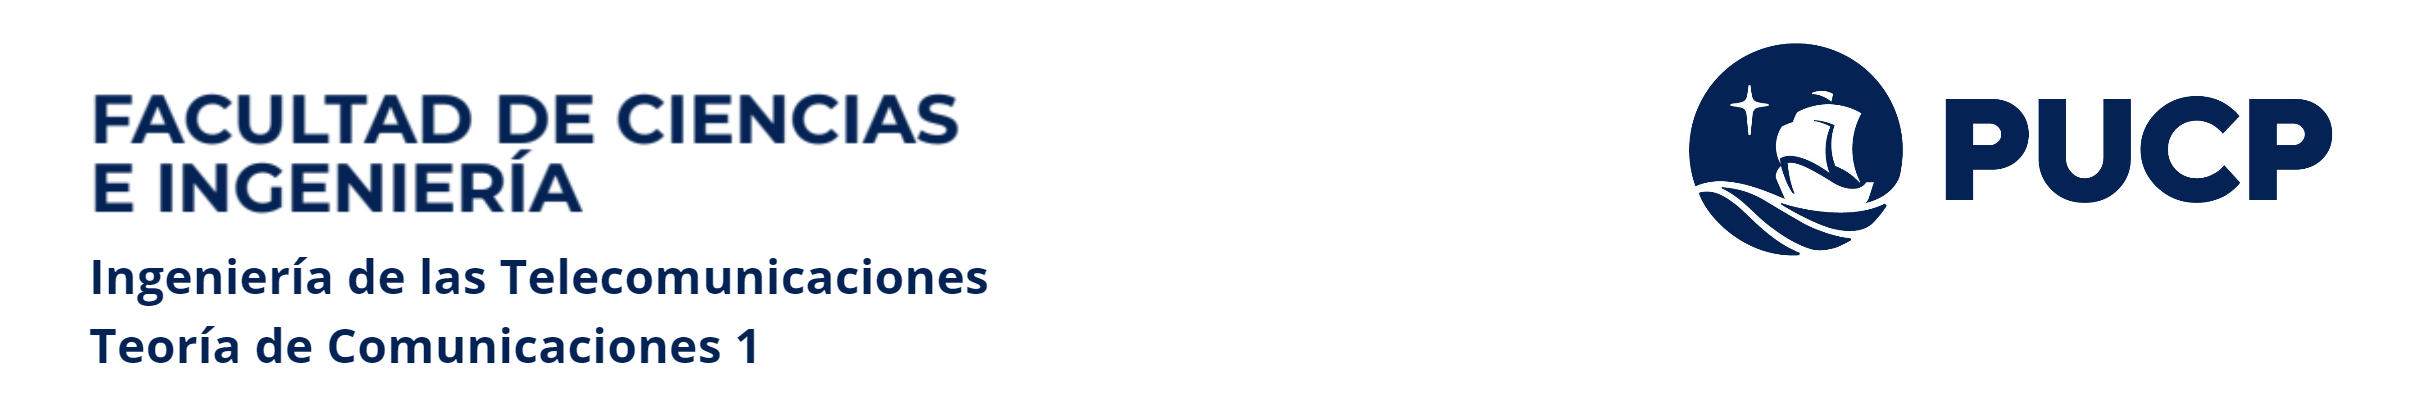

# Capítulo 2. Análisis y transmisión de señales

Luis Ángelo Velarde Criado

## **Antes de empezar**

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

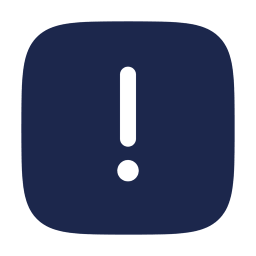 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

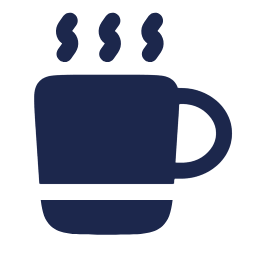 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

La iconografía del documento es la siguiente:

- 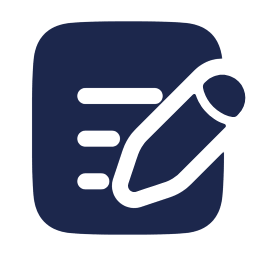** Pregunta.**

- 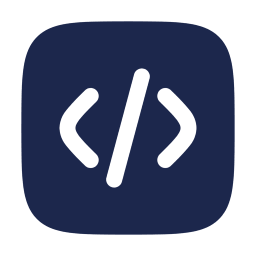 **Actividad. **

-  **Observación:**

- 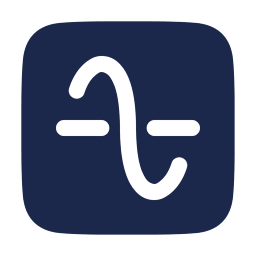 **Ejercicio 1.9 **

-  **Dato Interesante.**

## **Objetivos**

De acuerdo al sílabo del curso, al final de capítulo el alumno estará en condiciones de:	

- Analizar y comparar señales en el dominio del tiempo y de la frecuencia resaltando las características más importantes.	

- Representar gráficamente señales de diferentes características en el dominio del tiempo y la frecuencia.	

- Entender el proceso de muestreo de las señales y los requerimientos que plantea.

Estos objetivos contribuyen a los resultados de aprendizaje del curso:

- RA2: Analiza un sistema de comunicación analógico usando las herramientas de análisis espectral (en el dominio del tiempo y de la frecuencia).

- RA4: Analiza los parámetros de sistemas y señales de comunicación analógicos utilizando adecuadamente la instrumentación necesaria y sustentando sus resultados.

## **Contenidos** 

Los contenidos del curso son los que se indican a continuación en el diagrama partiendo del ya conocido análisis temporal para llegar a través del uso de las herramientas descritas al análisis en frecuencia de diversas señales, culminando con un ejercicio muy interesante como es el caso del muestreo de señales.

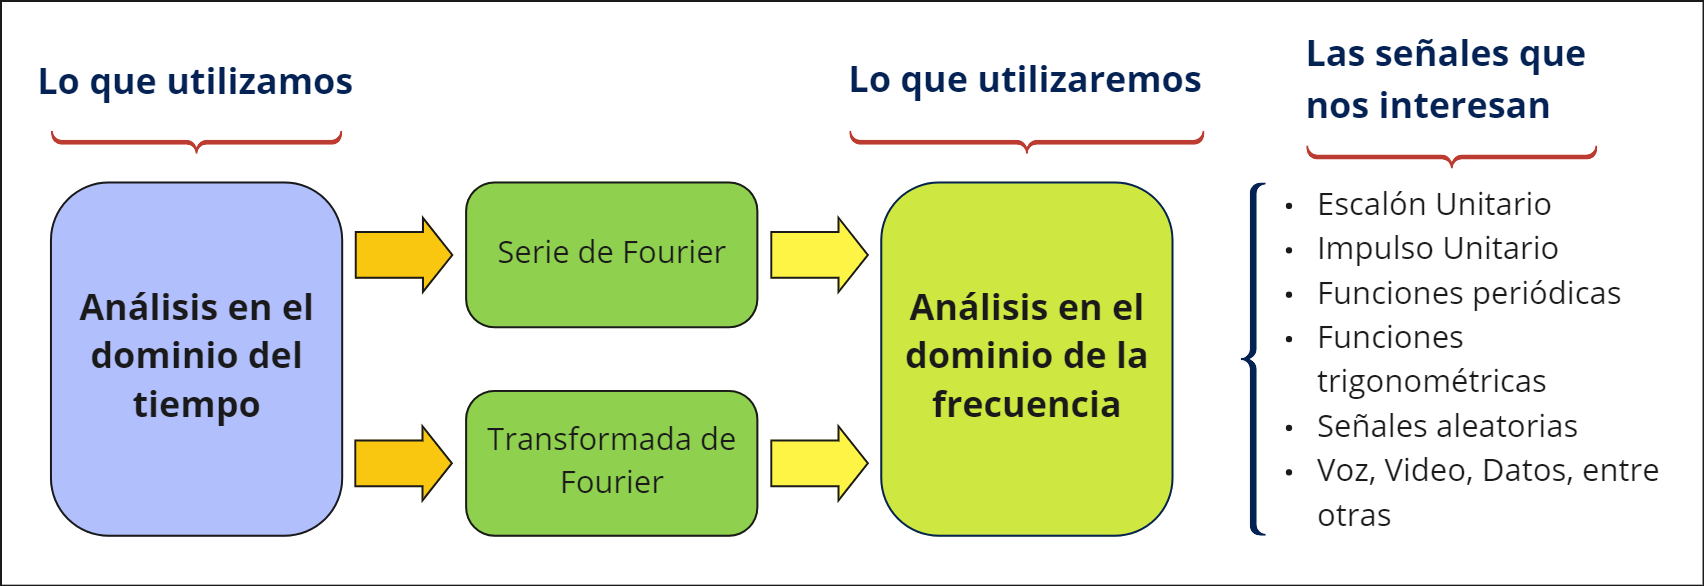

Figura 2.1 Esquema del progreso en en análisis de señales en el capítulo 2

Este análisis nos permitirá entender mucho mejor a las señales tal y como hicimos en el ejercicio mental y, además, nos permitirá sentar las bases para poder transmitir las señales de forma adecuada, lo cual constituye el objetivo final del curso.

Posteriormente, con la capacidad adquirida del análisis en frecuencia, podremos ser capaces de entender como funciona un sistema de comunicación bajo condiciones mínimas de operación que nos llevarán al concepto de los Sistemas Lineales e Invariantes en el Tiempo.

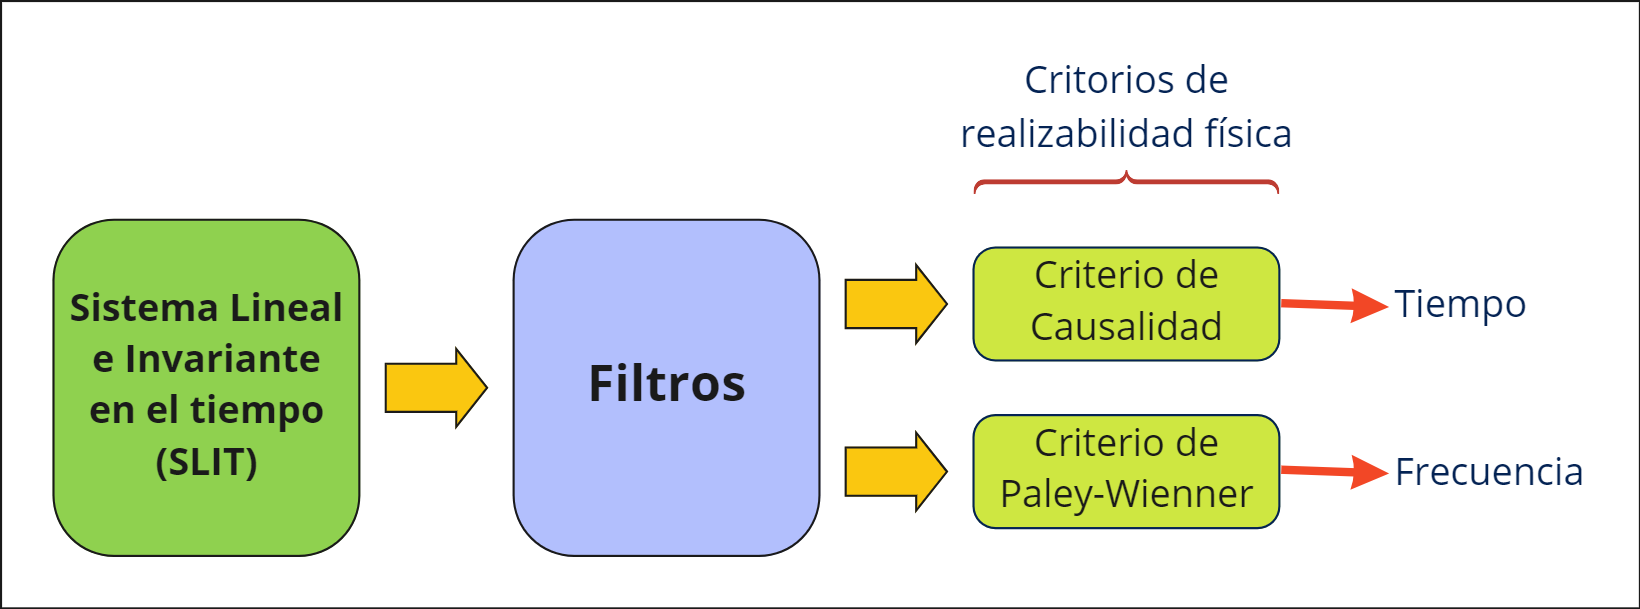

Figura 2.2 Esquema de trabajo con los sistemas lineales e invariantes en el tiempo

## Resumen

Ahora sí echaremos mano de las herramientas aprendidas en los cursos previos de matemática de Fourier y análisis de señales y sistemas. Pese a que se recomienda un repaso de los temas vistos en estos cursos, en este capítulo realizaremos un repaso (muy rápido) de los detalles más importantes de series y transformadas de Fourier cambiando un poco la perspectiva , pues mientras en los cursos previos la preocupación era entender la esencia matemática, en este curso daremos por sentado (después de repasar) el conocimiento del cálculo y nos concentraremos en su uso como herramienta en el análisis de las señales que queremos transmitir.

En la presente unidad, por lo tanto, se aprenderá a analizar las señales desde una perspectiva nueva. Ahora vamos a analizar los diferentes tipos de señales existentes (seno, coseno, exponencial, impulsivas, pulsos, trenes de pulsos, señales de voz, etc.) en el dominio de la frecuencia. 

Empezaremos resumiendo algunos conceptos matemáticos (algo viejos) y los iremos relacionando entre si en el transcurso del capítulo para llegar a nuestro objetivo. Como mencionamos, estas definiciones no son nuevas y muchas de ellas las puede revisar en el libro: “Análisis de Fourier” del autor Hwei P. Hsu

Gracias a las herramientas que aprenderemos seremos capaces de analizar las señales de una forma única, pero que a la vez será muy intuitiva pues es una tarea que hemos venido haciendo desde hace muchos año. Recordemos que cuando escuchamos música y describirla hablamos de bajos, medios o agudos; de la misma forma, cuando escuchamos una radio, palabras como sintonizar, vienen a nuestra mente, entre otros momentos en los que de manera natural el dominio de la frecuencia nos acompaña. Por lo tanto y antes de continuar, y para tener una idea más exacta de lo que seremos capaces de lograr haremos un ejercicio mental sencillo. 

 **Pregunta 1. **Pensemos por un momento en la radio FM. A medida que buscamos una emisora ¿Qué es lo que percibimos? tratemos de graficar lo que percibes al escuchar desde los 88MHz hasta los 108MHz considerando como eje Y el nivel de volumen que percibes. ¿Qué ocurre entre radio y radio? Mira el video a continuación para recordar: [Video búsqueda estación FM](https://youtu.be/qH5AMYmef3E?si=19WI5fYLo5vMtIPK)

Bien, lo que hemos obtenido es una gráfica Amplitud versus frecuencia, más conocido como un “espectro en frecuencia”. Ahora les dejo un gráfico para que lo analicen y lo comparen con lo que visualizaron en el ejercicio mental. En este caso es una señal aleatoria en el dominio de la frecuencia. 

#### Actividad: Cómo cambia el tamaño del Ruido

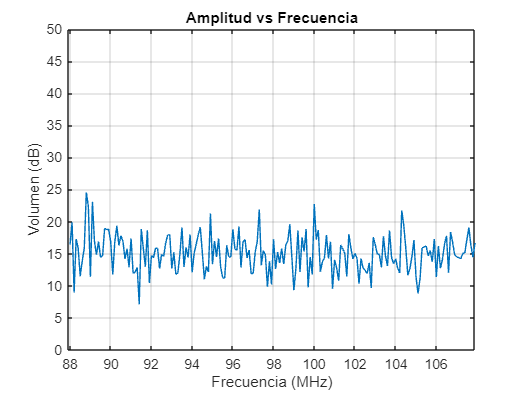


close all;
clear all;
clc;
%código ejemplo para señal aleatoria
frec = 88:0.1:108;
y1= 15*ones(size(frec));
DB = awgn(y1,15,'measured');  %Varia la SNR
plot(frec, DB); grid; title('Amplitud vs Frecuencia');
axis([88 108 0 30]);
xlabel('Frecuencia (MHz)'); ylabel('Volumen (dB)');

xlim([87.9 107.9])
ylim([0 50])

clear frec y1 DB


Código 2.1 Señal de ruido (SNR variable)

 **Pregunta 2. **¿Qué es lo que se aprecia en los ejes horizontal y vertical de la gráfica? ¿Qué unidades tiene? ¿Qué características de magnitud presenta la gráfica? ¿Cómo cambia la señal conforme mueves el slider?

Con estas interrogantes empezaremos el capítulo de Análisis de Señales. No te preocupes por tener todas las respuesas, la idea es que desde las preguntas construyamos el conocimiento.

## 1. Análisis de señales

Luego de haber analizado los diferentes tipos de señales existentes (seno, coseno, exponencial, impulsivas, pulsos, trenes de pulsos, etc.) en cursos anteriores, vamos a analizarlas desde una perspectiva diferente: el dominio de la frecuencia. Así que empezaremos a resumir algunos conceptos matemáticos y los iremos relacionando en el transcurso del capítulo para llegar a nuestro objetivo. Es necesario mencionar que estas definiciones no son nuevas y en este caso, la mayoría han sido tomadas del libro: “Análisis de Fourier” del autor Hwei P. Hsu.

### 1.1 Funciones Periódicas

Una función periódica se puede definir como una función para la cual

$f(t)=f(t+T)$   **(1.1)**

para todo valor de** t. **La constante mínima T que satisface la relación (1.1) se llama ***periodo ***de la función. Mediante repetición de (1.1) se obtiene

$f(t)=f(t+nT),n=0, \pm1,\pm2\ldots$   **(1.2)**

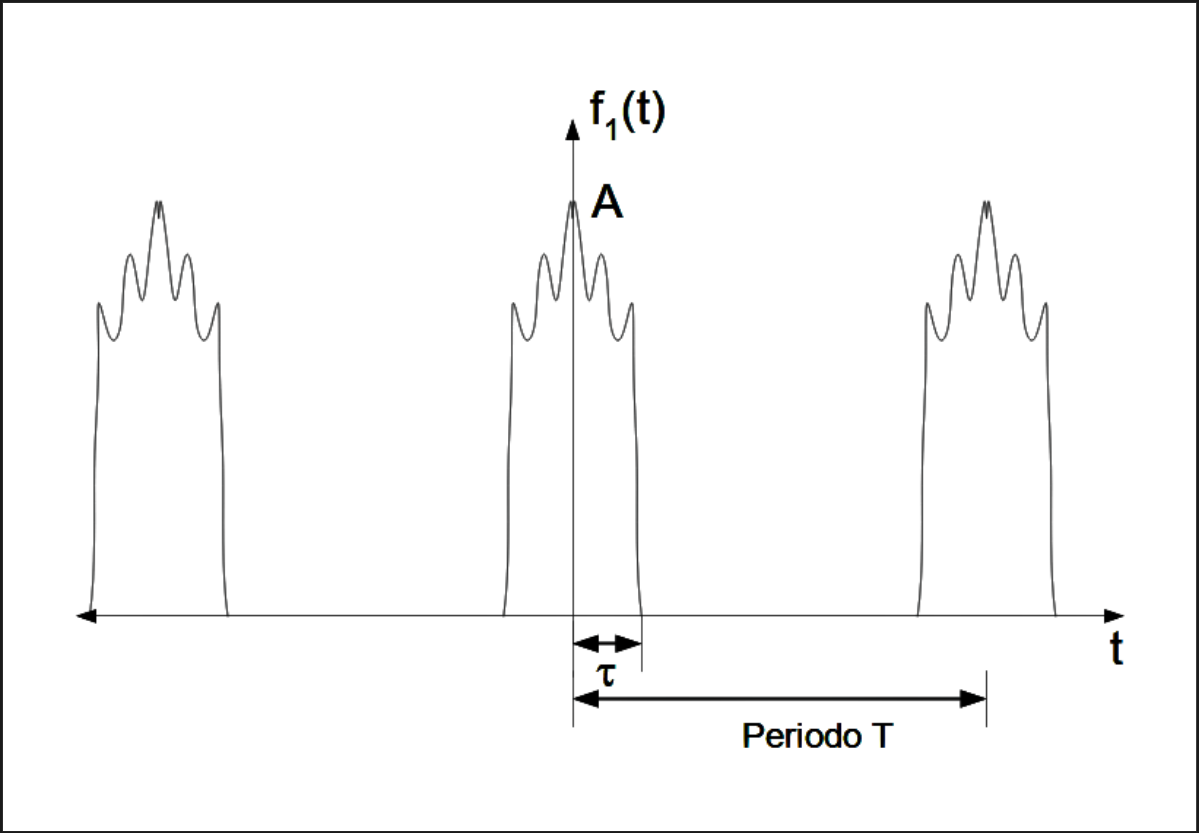

Figura 2.3 – Características de una función periódica $f_1 \left(t\right)$

####  Actividad: Ejemplo de Funciones Periódicas

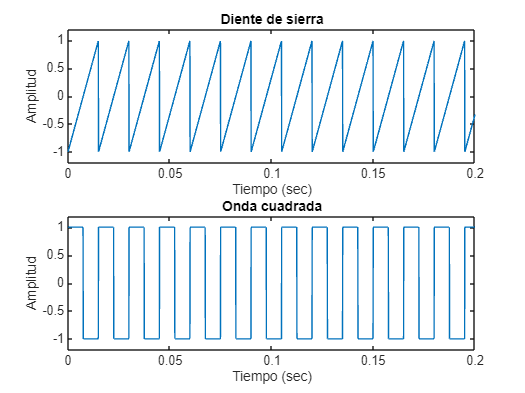

close all;
clear all;
clc;
fs = 10000;
t = 0:1/fs:1.5;
T=0.015; % Variar periodo
x1 = sawtooth(2*pi*t./T);
x2 = square(2*pi*t./T);

subplot(2,1,1)
plot(t,x1)
axis([0 0.2 -1.2 1.2])
xlabel('Tiempo (sec)')
ylabel('Amplitud') 
title('Diente de sierra')

subplot(2,1,2)
plot(t,x2)
axis([0 0.2 -1.2 1.2])
xlabel('Tiempo (sec)')
ylabel('Amplitud')
title('Onda cuadrada')

Código 2.2 Señales periódicas (periodo variable)

####  Actividad: Ejemplo de Funciones Aperiódicas

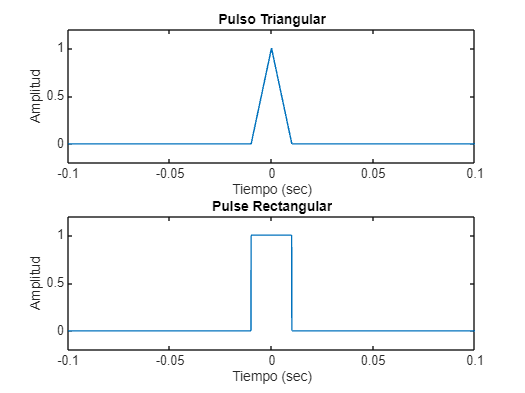

close all;
clear all;
clc;
fs = 10000;
t = -1:1/fs:1;
x1 = tripuls(t,20e-3);
x2 = rectpuls(t,20e-3);

figure
subplot(2,1,1)
plot(t,x1)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Tiempo (sec)')
ylabel('Amplitud')
title('Pulso Triangular')

subplot(2,1,2)
plot(t,x2)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Tiempo (sec)')
ylabel('Amplitud')
title('Pulse Rectangular')

Código 2.3 Señales aperiódicas

 **Pregunta 3. **Compara lo que has visto con la señales que te dejamos en Matlab ¿Reconoces sus características?.

### 1.2 Funciones Ortogonales

Un conjunto de funciones $f_k \left(t\right)$ es ortogonal en un intervalo $a$ si para dos funciones $f_m \left(t\right)$ y $f_n \left(t\right)$ pertenecientes al conjunto $f_k \left(t\right)$, cumple:

$\int f_m(t)f_n(t)dt=
\left\lbrace 
\begin{array}{l}
0\quad \ para \ m \neq n\\
r_n\quad para \ m=n
\end{array}
\right\rbrace$  **(1.3)**

 **Ejercicio 1.1. Calcular y analizar las siguientes expresiones:**


$$\int \cos (m\omega_0t)dt=$$

$$\$$



$$\int \sin (m\omega_0t)dt=$$

$$\$$



$$\int \cos (m\omega_0t) \cos (n\omega_0t) dt=$$

$$\$$



$$\int \sin (m\omega_0t) \sin (n\omega_0t) dt=$$

$$\$$



$$\int \sin (m\omega_0t) \cos (n\omega_0t) dt=$$

$$\$$


No olvidemos que falta analizar el resultado. Si sospechamos que al ser un ejercicio de funciones ortogonales vamos a encontrar que las funciones analizadas son ortogonales estamos en lo correcto. 

 **Pregunta 4. **¿Para qué condiciones se ha obtenido los resultados? ¿Hay una sola respuesta o varias dependiendo de las condiciones planteadas? ¿Cuáles son las funciones que se considerarán ortogonales?

### 1.3 Mirada al pasado de la ortogonalidad

#### 1.3.1 Vectores linealmente dependientes

Al multiplicar un vector por un escalar obtenemos otro vector que pertenece tiene igual dirección pero cambia su módulo y (dependiendo del signo del número) puede cambiar el sentido. Este vector es linealmente dependiente del primero.

- Considerando los vectores U = (2, 4) = 2 (1, 2) y V = (1, 2). Estos pueden sumarse dando como resultado el vector nulo, por lo tanto, son ***linealmente dependientes***.

- Es decir, los vectores U y V son linealmente dependientes cuando los escalares a, b para los cuales se cumple: a. U + b. V = 0 no son nulos (no valen cero).

#### 1.3.2 Vectores linealmente independientes

La definición es evidente, si los valores de a y b, para los cuales, la suma da un vector nulo, sólo ocurre si son cero, entonces, los vectores son linealmente independientes.

- Para que el resultado a. U + b. V = 0  → si a = 0 y b = 0 (la única opción) el sistema es linealmente independiente.

#### 1.3.3 Combinación lineal: Caso de los vectores

Al ser U y V linealmente independientes pueden, al sumarse, generar cualquier vector del plano (llamémosle W). Así que U y V constituyen una base de los vectores del plano si todo vector W del plano se puede expresar de manera única como combinación lineal de U y V, es decir que a. U + b. V = W 

#### 1.3.4 Combinación lineal: Caso de los vectores

Una base ortogonal de los vectores del plano es una base de vectores ortogonales unitarios donde, $\overset{\wedge }{i}$ es el vector unitario de dirección horizontal (eje x), mientras que $\overset{\wedge }{j}$ es el de dirección vertical (eje y) y el vector $\overset{\wedge }{k}$ representa la tercera dimensión (eje z). Así si R = (2, 3, 5)  puede escribirse como  R = 2 $\overset{\wedge }{i}$ + 3 $\overset{\wedge }{j}$ + 5 $\overset{\wedge }{k}$.

Recordamos finalmente, que un vector unitario es un vector cuyo módulo es 1.

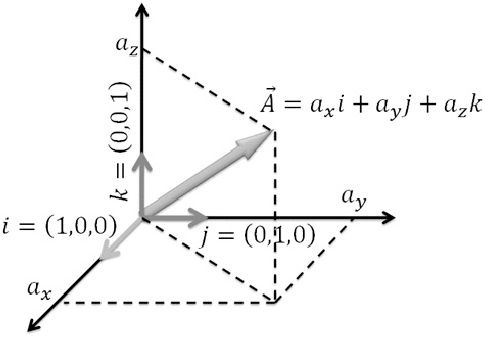

Figura 2.4 Descomposición de vector en componentes y vectores unitarios.

 **Pregunta 5. **¿Qué es lo que entiendes por ortogonalidad ahora? ¿Recuerdas otras referencias para este tema adempas de los vectores? ¿Qué relación tiene con el cálculo basado en integrales hecho previamente?

 **Observación:** Antes de entrar al siguiente punto te recomiendo que revises las principales relaciones e identidades trigonométricas, así como los valores de las funciones trigonométricas de algunos ángulos notables.

### 1.4 Series de Fourier

Sea la función $f\left(t\right)$  una función periódica de período $T$, la cual se puede representar por la serie trigonométrica:

$f(t) = \frac{1}{2}a_0
+a_1\cos\omega_0t
+a_2\cos2\omega_0t
+\ldots
+b_1\sin\omega_0t
+b_2\sin2\omega_0t
+\ldots
\\
f(t) = 
\frac{1}{2}a_0+
\sum_{n=1}^{\infty}\left(a_n\cos n\omega_0t + b_n\sin n\omega_0t\right)$  **(1.4)**

donde $\omega_0 =2\pi /T\ldotp$

 **Pregunta 6.** ¿Qué conclusiones podemos obtener a partir de la estructura de la serie de Fourier? ¿Para qué sirve la serie de Fourier?

Es interesante como ahora todo encaja, si las funciones que hemos descrito en el ejercicio 1.1 (constante, $\cos \left(n\omega {\;}_0 t\right)$) y $\sin \left(n\omega {\;}_0 t\right)$ ) son ortogonales, entonces son independientes entre si a través de la variable “frecuencia” lo que implica que cualquier función, en nuestro caso las periódicas, pueden ser representadas como una combinación de las funciones ortogonales halladas asignándoles pesos adecuados $\left(a_n ,b_n ,a_0 \right)$

Utilizando las condiciones de ortogonalidad se puede demostrar que los valores de estas constantes son:

$\left\lbrace 
\begin{array}{l}
a_0=\frac{2}{T}\int_{-T/2}^{T/2}f(t)dt\\
a_n=\frac{2}{T}\int_{-T/2}^{T/2}f(t)\cos(n\omega_0t)dt,\quad n=0,1,2,3,\ldots\\
b_n=\frac{2}{T}\int_{-T/2}^{T/2}f(t)\sin(n\omega_0t)dt
\end{array}
$   **(1.5)**

 **Ejercicio 1.2. Ahora toca demostrar las expresiones (te recomiendo usar la ortogonalidad)**

Para complementar un poco el análisis realizado se puede mencionar que las componentes senoidales de frecuencia $\omega_n =n\omega_0 \;$se denomina la ***enésima armónica ***de la función periódica. La primera armónica se conoce como la ***componente fundamental*** porque tiene el mismo periodo de la función y $\omega_0 =2\pi \;f_0 =2\pi /T$ se conoce como ***frecuencia angular fundamental***. Los coeficientes que hemos obtenido del ejercicio y que denominaremos $C_n$ y el ángulo $\theta_n$ se conocen como ***amplitudes armónicas ***y ***ángulos de fase******, ***respectivamente.

Ahora que ya recordamos como calcular los coeficientes de la serie de Fourier, toca determinar cual es la serie de Fourier para algunas de las funciones que hemos mencionado al inicio y que siempre nos van a acompañar.

 **Ejercicio 1.3 Determinar la Serie de Fourier de la función definida como:**

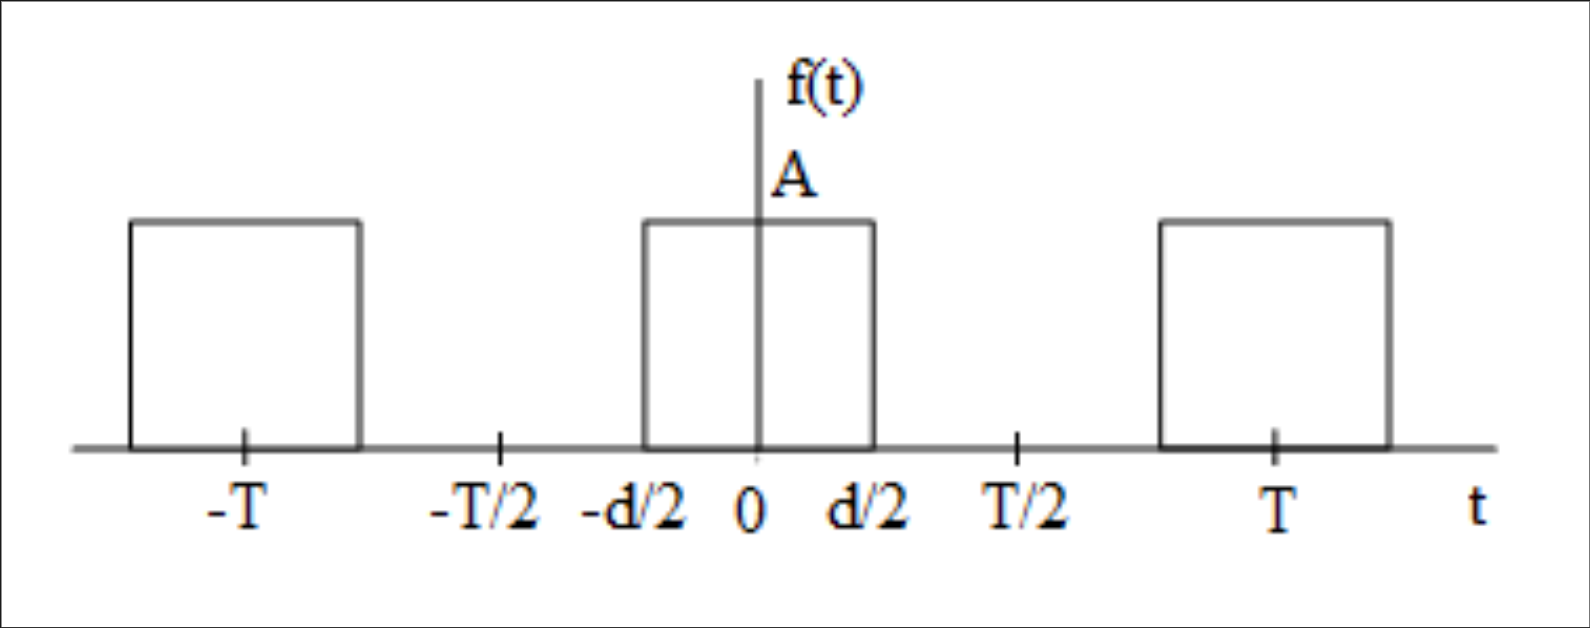

Figura 2.4 – Tren de pulsos

 **Ejercicio 1.4 Desarrollar la función **$f\left(t\right)=\sin^3 t$ **en serie de Fourier:**

Respuesta.- Si pareció muy complicado resolver el ejercicio utilizando las expresiones de los coeficientes de la Serie de Fourier, ahora convierte la expresión cúbica usando identidades trigonométricas hasta que quede en términos de coseno del ángulo doble o triple, seno del ángulo doble o triple, etc. Cuando llegues hasta ahí, habrás llegado a la respuesta. La pregunta es si siempre podemos hacer eso, por lo cual es necesario plantear algunas condiciones.

 **Observación:** Existen condiciones para la existencia de la serie de Fourier . Recomendamos repasar las condiciones de Dirichlet.

#### 1.4.1 Algunas propiedades básicas

Antes de continuar, es bueno recordar algunas propiedades que has visto previamente. 

- ***Funciones pares e impares:***

Lo primero es recordar las funciones pares e impares, algo que nos va a ayudar enormente, pues la base de nuestro análisis descansa en funciones como senos y cosenos.

Se dice que una función es ***par ***si satisface la condición: $f\left(-t\right)=f\left(t\right)$

Se dice que la función es ***impar ***si satisface la condición: $f\left(-t\right)=-f\left(t\right)$

Veamos un par de ejemplos en Matlab para comparar los 2 tipos de funciones y sus gráficas. Recuerda sobre todo la parte gráfica, visualizar las funciones te va a ayudar muchísimo en el curso,

####  Actividad: Ejemplo de Funciones Pares e Impares

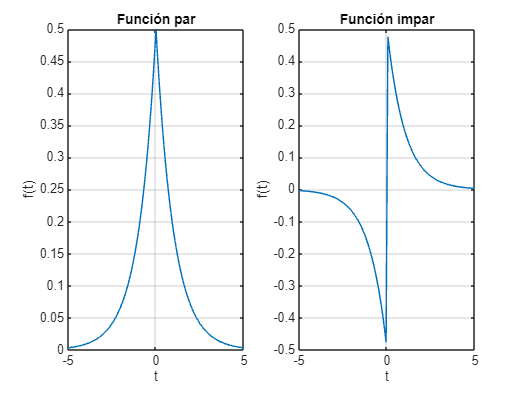

close all;
clear all;
clc;
t = -5:0.05:5;
f = @(t) exp(-t).*(t>0) + 0.5*(t==0);
fpar = 0.5*(f(t)+f(-t));
fimpar = 0.5*(f(t)-f(-t));
figure;
   subplot(1,2,1);
   plot(t,fpar); grid; title('Función par'); xlabel('t'); ylabel('f(t)');
   subplot(1,2,2);
   plot(t,fimpar); grid; title('Función impar'); xlabel('t'); ylabel('f(t)');

clear f t fpar fimpar


Código 2.4 Funciones pares e impares

 **Pregunta 7.** Recordemos en el gráfico de las funciones par e impar las simetrías existentes.¿Cuáles son?

Algunas propiedades de las funciones pares e impares:

1) Sean las funciones $f_1 \left(t\right)$	y $f_2 \left(t\right)$ ***pares*** y $g_1 \left(t\right)$y $g_2 \left(t\right)$ ***impares***, entonces se cumple

		$f_1 \left(t\right)\;x\;f_2 \left(t\right)$ es una función ***par***

		$g_1 \left(t\right)\;x{\;g}_2 \left(t\right)$ es una función ***par***

		$f_1 \left(t\right)\;x{\;g}_1 \left(t\right)$ es una función ***impar***	

2) Cualquier función puede expresarse como la suma de dos funciones componentes, de las cuales una es par y la otra impar	

3) Si $f_1 \left(t\right)$ es par, se cumple que: $\int_{-\infty }^{+\infty } f\left(t\right)\textrm{dt}=2\int_0^{+\infty } f\left(t\right)\textrm{dt}$

4) Si $g_1 \left(t\right)$ es impar, se cumple que: $\int_{-\infty }^{+\infty } f\left(t\right)\textrm{dt}=0$ y $f\left(0\right)=0$

- ***Simetría de media onda:***

Si una función *f(t)*es periódica con periodo T, entonces se dice que tiene ***simetría de media onda ***si:

$f(t)=-f\left(t+\frac{1}{T}\right)$  **(1.6)**

 **Pregunta 8.** ¿Cuál sería el gráfico de una función como esta? ¿Qué funciones conocidas tienen esta simetría?

- ***Simetría de cuarto de onda:***

Si una función $f\left(t\right)$ es periódica con periodo $T$, tiene simetría de media onda y a demás es par o impar se dice que tiene ***simetría de cuarto de onda par o impar***.

 **Pregunta 9.** ¿Cuál sería el gráfico de una función como esta? ¿Qué funciones conocidas tienen esta simetría?

Una pregunta para analizar:

 **Ejercicio 1.5 La siguiente función, ¿es simétrica?:**

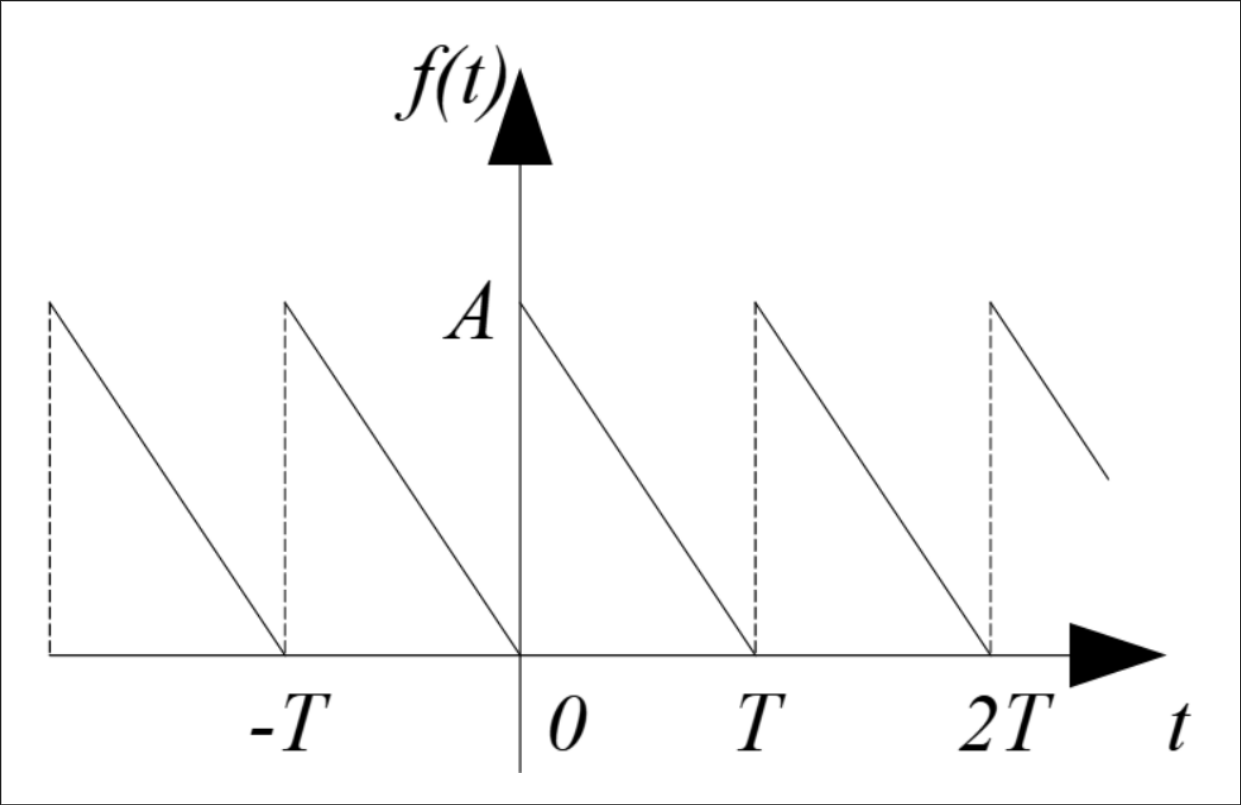

Figura 2.5 – Tren de diente de sierra

Ahora que hemos recordado estas propiedades de funciones podemos plantear algunas propiedades de las Series de Fourier (que de hecho recomendamos demostrar), y que luego utilizaremos:

- Si $f\left(t\right)$ es una función periódica par se cumple que su serie de Fourier será:

$f(t)=\frac{1}{2}a_0+\sum_{n=1}^{\infty} a_n\cos(n\omega_0t),\quad 
donde \quad \omega_0=\frac{2\pi}{T}$  **(1.7)**

$con:\\
a_n=\frac{4}{T}\int f(t)\cos(n\omega_0t)dt
\qquad \qquad\qquad\qquad\qquad$  **(1.8)**

- Si $f\left(t\right)$ es una función periódica impar se cumple que su serie de Fourier será:

$f(t)=\frac{1}{2}a_0+\sum_{n=1}^{\infty} b_n\sin(n\omega_0t),\quad 
donde \quad \omega_0=\frac{2\pi}{T}$  **(1.9)**

$con:\\
b_n=\frac{4}{T}\int f(t)\sin(n\omega_0t)dt
\qquad \qquad\qquad\qquad\qquad$  **(1.10)**

- Si $f\left(t\right)$ es una función periódica con simetría de media onda, entonces su Serie de Fourier tiene sólo armónicas impares.

- Si $f\left(t\right)$ es una función periódica con simetría de cuarto de onda par, entonces su Serie de Fourier tiene sólo armónicas impares de términos de coseno.

- Si $f\left(t\right)$ es una función periódica con simetría de cuarto de onda impar, entonces su Serie de Fourier tiene sólo armónicas impares de términos de seno.

- Si $f\left(t\right)=\frac{1}{2}a_0 +\sum_{n=1}^{\infty \;} \left(a_n \textrm{cosn}\omega {\;}_0 t+b_n \textrm{sinn}\omega {\;}_0 t\right)$, entonces $f^{\prime } \left(t\right)=\sum_{n=1}^{\infty \;} \left({-a}_n \textrm{sinn}\omega {\;}_0 t+b_n \textrm{cosn}\omega {\;}_0 t\right)$. ***¿Esto es válido siempre?***

#### 1.4.2 Un caso especial. La función impulso

Vamos a recordar alguna de las propiedades de la función impulso así como algunas de sus definiciones más conocidas.

La función impulso unitario $\delta \left(t\right)$ o función delta se expresa como:

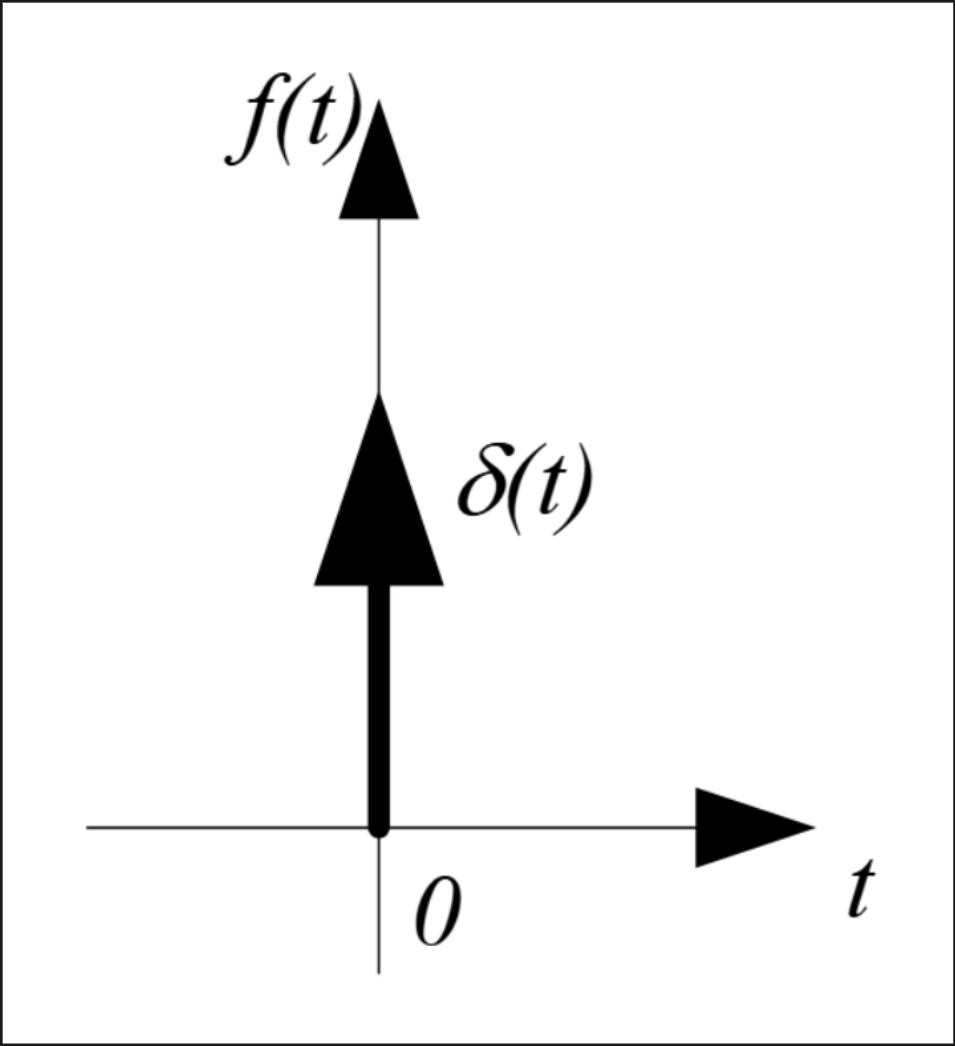

Figura 2.6 – Impulso unitario/Función Delta en el Dominio del Tiempo

$\delta(t)=
\left\lbrace 
\begin{array}{l}
0 \quad t\neq0,\\
\infty \quad t=0
\end{array}\\
\int_{-\infty}^{\infty}\delta(t)dt=\int_{0-}^{0+}\delta(t)dt=1$  **(1.11)**

 **Pregunta 10.**  ¿Cuál es el valor del impulso en el origen? ¿Cuál es su área?

Esta es una de las formas de definir la función delta, pero no es la única, veamos algunas otras a continuación.

- Desde un pulso rectangular: $\delta \left(t\right)=\lim_{\tau \longrightarrow \infty } \frac{\;1}{\tau }\left\lbrack u\left(t+\frac{\;\tau }{2}\right)-u\left(t-\frac{\;\tau }{2}\right)\right\rbrack$ **(1.12)**

####  Actividad: Pasando de la función Pulso a la función Impulso 

Dado que este es el caso más sencillo podemos insertar un código en Maltab que te ayudará a visualizar que ocurre cuando nos vamos acerando al límite en este caso. :

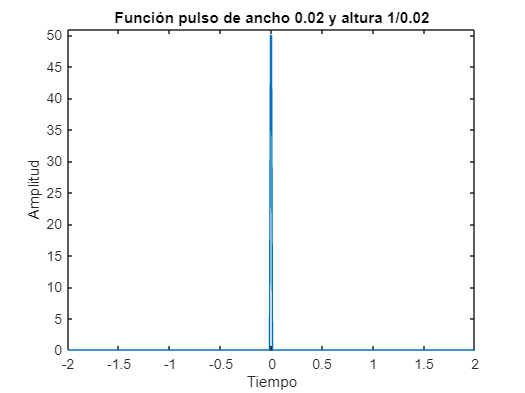

close all;
clear all;
clc;
t = 0.02;  % Cambia el valor de t según sea necesario
t_vec = -5:0.01:5;  % Vector de tiempo para graficar la función

% Generar el pulso rectangular usando rectpuls
y_rect = rectpuls(t_vec, t);

% Ajustar la amplitud según 1/t
y = y_rect * (1/t);

% Graficar la función
plot(t_vec, y);
xlabel('Tiempo');
ylabel('Amplitud');
title(sprintf('Función pulso de ancho %g y altura 1/%g', t, t));

xlim([-2.00 2.00])
ylim([0 51])

clear t t_vec y_rect y;


Código 2.5 Función pulso (ancho de pulso variable)

- Desde un pulso triangular: $\delta \left(t\right)=\lim_{\tau \longrightarrow \infty } \frac{\;1}{\tau }\left\lbrack 1-\frac{\;\left|t\right|}{\tau }\right\rbrack ,\left|t\right|<\tau$                  **(1.13)**

- Desde una exponencial de dos lados: $\delta \left(t\right)=\lim_{\tau \longrightarrow \infty } \frac{\;1}{\tau }e^{-\left|2t\right|/\tau \;}$               **(1.14)**

- Desde un pulso: gaussiano: $\delta \left(t\right)=\lim_{\tau \longrightarrow \infty } \frac{\;1}{\tau }e^{-\pi \;{\left(t/\tau \;\right)}^2 }$                             **(1.15)  **

- Desde una función de muestreo: $\delta \left(t\right)=\lim_{\tau \longrightarrow \infty } \frac{\;1}{\tau }\textrm{Sa}\left(\pi t\tau \right)$                      **(1.16)**

- Desde una función de muestreo cuadrado: $\delta \left(t\right)=\lim_{\tau \longrightarrow \infty } \frac{\;1}{\tau }{\textrm{Sa}}^2 \left(\pi t\tau \right)$     **(1.17)**

 **Pregunta 11.**  ¿Cómo sería la gráfica de estas expresiones antes de aplicar el límite? ¿Cómo variaría la gráfica conforme $\tau \to 0$?

**Propiedades del impulso unitario:**

Recordemos ahora algunas de las propiedades más resaltantes:

- Para una función $f\left(t\right)$ continua:

$\int_{-\infty}^{\infty}\delta(t-t_0)f(t)dt
= 
\int_{-\infty}^{\infty}f(t)\delta(t+t_0)dt
=
f(t_0)$      **(1.18)**

- Para una función $f\left(t\right)$ continua en $t=t_0$ si $a<b$:

$\int_{a}^{b}\delta(t-t_0)f(t)dt
= 
\left\lbrace 
\begin{array}{l}
f(t_0) \quad para \ a<t_0<b\\
0 \quad \ \ \ para \ b<t_0<a
\end{array}$      **(1.19)**

- Para $t=t_0$ si $a<b$:

$\int_{b}^{a}\delta(t-t_0)dt
= 
\left\lbrace 
\begin{array}{l}
1 \quad para \ a<t_0<b\\
0 \quad para \ b<t_0<a
\end{array}$           **(1.20)**

- Se cumple que:

$f(t)\delta(t)=f(0)\delta(t)$      **(1.21)**

- Si definimos la función $\delta_T \left(t\right)$ como un tren periódico de impulsos unitarios, se cumple que:

$\delta_T(t)=\sum_{-\infty}^{+\infty}\delta(t-nT)=\frac{1}{T}+\frac{2}{T}\sum_{n=1}^{+\infty}\cos(n\omega_0t),\quad \omega_0=\frac{2\pi}{T}$      **(1.22)**

#### 1.4.3 La función escalón unitario

Para esta función bastante conocida colocaremos sólo su definición y la relación que tiene con la función anterior, pero dejamos a continuaci

####  Actividad: La función escalón

Te dejo la gráfica de la función en Matlab para que la reconozcas en códigos posteriores.

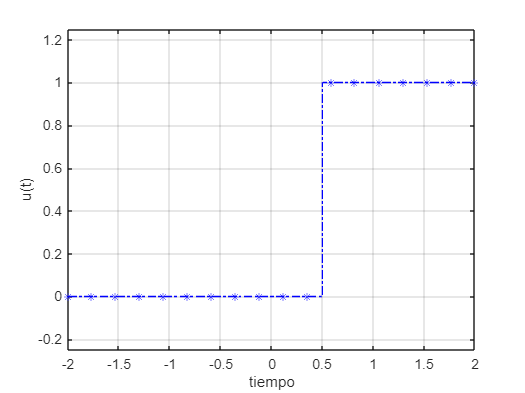

close all;
clear all;
clc;
syms t;
figure;
t0= -0.5;
fplot(heaviside(t+t0),'-.*b');grid;
axis([-2, 2 -0.25 1.25]);
xlabel('tiempo'); ylabel('u(t)');

clear t;


Código 2.6 Función escalón

Donde se cumple:

$u(t)=\left\lbrace 
\begin{array}{l}
1\quad t>0\\
0\quad t<0
\end{array}\right.$      **(1.23)**

Ojo que la función **no está definida en cero**. Ahora si podemos colocar la propiedad:

$u'(t)=\frac{du(t)}{dt} =\delta(t)$      **(1.24)**

 **Ejercicio 1.6 Ahora toca calcular la Serie de Fourier de la siguiente función. :**

Figura 2.7 – Función Tren de Pulsos en el Dominio del Tiempo

#### 1.4.4 Forma compleja de la Serie de Fourier

Procedamos directamente a dar la expresión correspondiente:

$f(t)=\sum_{n=-\infty }^{\infty } c_n e^{\mathrm{jn}{\omega}_0 t}$      **(1.25)**

donde

$c_n =
\frac{1}{T}\int_{-T/2}^{T/2} f(t)e^{-jn{\omega}_0 t} dt,
n=\dots -3,-2,-1,0,+1,+2,+3,\dots$      **(1.26)**

Como ahora hemos extendido el análisis de la Serie de Fourier hacia funciones que toman valores complejos, es necesario también que recordemos la definición que colocamos para funciones ortogonales en funciones de valor complejo.

#### 1.4.5 Forma compleja de las funciones ortogonales

El conjunto de funciones complejas $f\left(t\right)$ se denomina ortogonal en el intervalo $a<t<b$ si:

$\int_{a}^{b} f_n(t)f^*_m(t)dt=\left\lbrace 
\begin{array}{l}
0\quad para \  n \neq m \\
r_n\quad para \ n = m
\end{array}\right.
$  donde f* es la función conjugada.       **(1.27)**

 **Ejercicio 1.7 Demostrar que la función de la Serie de Fourier **$\left\lbrace e^{\textrm{jn}\omega {\;}_0 t} \right\rbrace$** obedece a la ortogonalidad en el intervalo **$-\frac{T}{2}<t<\frac{T}{2}$** donde **$\omega {\;}_0 =\frac{2\pi \;}{T}$**:**

 **Ejercicio 1.8 Encuentre los coeficientes Cn para la función periódica del ejercicio 1.6 **

Como hemos calculado los coeficientes Cn de la función de tren de pulsos colocada vamos ahora a graficar estos coeficientes en función de la frecuencia. Escondido en este reultado está una nueva función, la función Sampling.

 **Pregunta 12.**  Respecto al ejercicio realizado, ¿Cómo describirías la respuesta? ¿Qué representa?

#### 1.4.6 La función Sa(x)

Luego de observar el resultado obtenido en el Ejercicio 1.8 encontramos una función de $C_n$ con el formato:

$C_n=\frac{Ad}{T}
\frac{\sin\left(\frac{n\pi d}{T}\right)}{\left(\frac{n\pi d}{T}\right)}$      **(1.28)**

Esta expresión tiene una particularidad,  la cual podemos apreciar en el gráfico de la misma en función de la frecuencia. Para hacer las cosas más sencillas, asumamos que el periodo $T=\frac{1}{4}$ y el ancho del pulso $d=\frac{1}{20}$. Con estos valores veamos la gráfica resultante:

####  Actividad: Mirando los Cn y la forma del Sa(x)

Te dejo una representación gráfica de los valores de magnitud de Cn en función de la frecuencia. Observa que varía y que no varía a partir del gráfico.

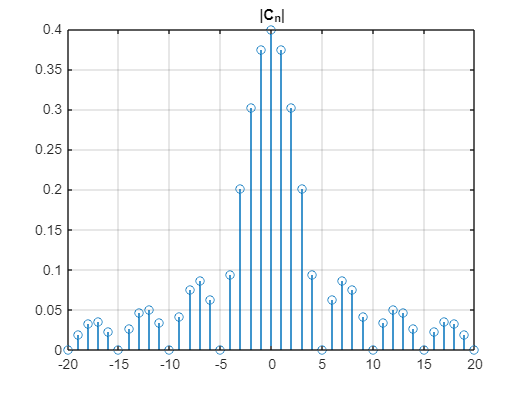

close all;
clear all;
clc;
A =2;
d = 1/20; T = 1/4 ;
mult = A*d/T;
w = -20:1:20;
f=@(w) mult*sinc(w*d/T);
sax = abs(f(w));
figure;
stem(w,sax); grid; title('|C_n|');

clear A d T mult f w sax; 


Código 2.7 Gráfico de los Cn en función de la frecuencia.

Ahora miremos la función que aparece como envolvente de los Cn. Como mencionamos esta es una función muy útil, ya sea que se le denomine Sa(x) o Sinc(x) hablamos de la Función Sampling o función de muestreo Su definición, si es que no la recordamos es:

$Sa(x)=\frac{\sin(x)}{x}=\text{sinc}(x)$        **(1.29)**

 **Dato Interesante. **Vale la pena mencionar que en este caso en particular la función **sinc** que utiliza MATLAB es una versión que se denomina normalizada, tal que:

$\text{sinc}(x)=\frac{sin(\pi x)}{\pi x}$        **(1.30)**

####  Actividad: Mirando la función Sa(x)

Acá apreciamos como cambia la función Sinc(x). 

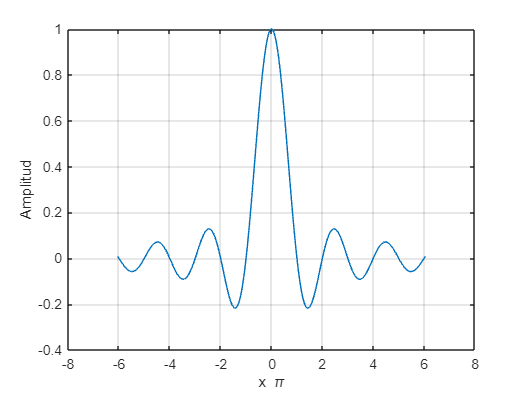

close all;
clear all;
clc;
x = 19; %Varia los limites 
t = -x:0.05:x; 
tw = t/pi;
f = @(t) sinc(t/pi); %se divide para que quede sin(t)/t. Ver en el Help de Matlab
sax = f(t);
figure;
plot(tw,sax); grid;  
xlabel('x \pi'); ylabel('Amplitud');

clear t tw f sax x


Código 2.8 Gráfico de función Sinc(x) - (límites variables)

Aplicando esto en los coeficientes Cn tenemos:


$$C_n=\frac{Ad}{T}\frac{\sin \left(\frac{n\pi d}{T}\right)}{\left(\frac{n\pi d}{T}\right)}
=
\frac{Ad}{T} Sa\left(\frac{n\pi d}{T}\right)$$


Esto termina de describir que la Serie Compleja de Fourier de un tren de pulsos está formada por coeficientes definidos por Cn pero que van cambiando a partir de las características de la función Sampling. 

 **Ejercicio 1.9 Deducir la Serie Compleja de Fourier del tren de pulsos periódico de impulsos unitarios**

### 1.5 La Integral de Fourier. La Transformada de Fourier

Cuando en una función $f\left(t\right)$ periódica de periodo $T$ llevamos el periodo al infinito , la función se convierte en no periódica y se puede representar de la siguiente forma:

$\begin{array}{l}
f(t)=\frac{1}{2\pi}\int^{+\infty}_{-\infty}F(\omega)e^{j\omega t}d\omega \ \text{donde}\\
F(\omega)=\int^{+\infty}_{-\infty}f(t)e^{-j\omega t}dt
\end{array}
$      **(1.31)**

De aquí aparece el par de transformada de Fourier con las operaciones:

$\begin{array}{l}
F(\omega)=\textbf{F}[f(t)]=\int_{-\infty}^{+\infty}f(t)e^{-j\omega t}dt \  \text{y}\\ 
f(t)=\textbf{F}^{-1}[F(\omega)]=\frac{1}{2\pi}\int_{-\infty}^{+\infty}F(\omega)e^{j\omega t}d\omega
\end{array}$      **(1.32)**

La condición de existencia de la Transformada de Fourier está dada por: $\int_{-\infty }^{+\infty } \left|f\left(t\right)\right|\textrm{dt}<\infty \;$, es decir que la integral debe ser finita.

Como sabemos que la función $f\left(t\right)$ es compleja podemos afirmar que:

$F(\omega)=R(\omega)+jX(\omega)=|F(\omega)|e^{j\varphi(\omega)}$       **(1.33)**

Donde $\left|F\left(\omega \right)\right|$ es el ***espectro de magnitud***  y $\varphi \left(\omega \right)$ es el ***espectro de fase***.

De aquí podemos deducir algunas expresiones y relaciones:

- $R\left(\omega \right)=\int_{-\infty \;}^{+\infty \;} f\left(t\right)\cos \left(\omega t\right)\textrm{dt}$      **(1.34)**

- $X\left(\omega \right)=\int_{-\infty \;}^{+\infty \;} f\left(t\right)\sin \left(\omega t\right)\textrm{dt}$	      **(1.35)**

- $R\left(\omega \right)$ es par y $X\left(\omega \right)$ es impar respecto a $\omega$.	

- Si $f\left(t\right)$ es real, entonces su espectro de magnitud es par y el espectro de fase es impar respecto a $\omega$.	

- Si la transformada de la función real $f\left(t\right)$ es real, entonces $f\left(t\right)$ es una función par de $t$. Si la transformada de la función real $f\left(t\right)$ es imaginaria pura, entonces $f\left(t\right)$ es función impar de $t$.

### 1.6 La Transformada de Fourier de funciones especiales

Hemos planteado una condición de existencia de la Transformada de Fourier, es decir que $\int_{-\infty \;}^{+\infty \;} \left|f\left(t\right)\right|\textrm{dt}<\infty \;$, pero esta condición no se cumple con algunas funciones como $\sin \omega {\;}_0 t,\cos \omega {\;}_0 t,u\left(t\right)$, etc.  ¿Cuál es la Transformada de Fourier de estas funciones?

En la tabla de propiedades colocada líneas abajo se indican las transformadas de estas funciones, queda como tarea el determinar como se llega a estos resultados.

### 1.7 La Transformada de Fourier de de una función periódica

Si tenemos una función periódica $f\left(t\right)$ sabemos por simple análisis que $\int_{-\infty \;}^{+\infty \;} \left|f\left(t\right)\right|\textrm{dt}=\infty \;$, entonces

 **Pregunta 13.**  ¿Cómo calculamos la Transformada de Fourier? ¿Cómo redefinimos f(t) para hacer el cálculo? ¿Hay una forma de representar una función periódica?

Para una función $f\left(t\right)$ periódica, la transformada de Fourier correspondiente está dada por:

$F(\omega)=2\pi \sum_{n=-\infty}^{+\infty}C_n\delta(\omega-n\omega_0)$       **(1.36)**

Donde $C_n$ representan a los coeficientes de Fourier.

 **Pregunta 14.**  Recordemos la propiedad número 39, ¿Es posible demostrarla ahora?

### 1.8 Propiedades de la Transformada de Fourier

A continuación en la tabla adjunta se indican las principales propiedades de las Transformadas de Fourier. Ojo que hay que demostrar las relaciones planteadas, pero eso lo dejamos para que lo realices en casa.

Tabla 2.1 – Tabla de funciones y sus transformadas


$$\left[\matrix{
\text{\#}     	& f(t) 	                                        & F(\omega)  \cr
1  		        & a_1f_1(t)+a_2f_2(t) 			& a_1F_1(\omega)+a_2F_2(\omega)	\cr
2  		        & f(at) 			                        & \frac{1}{|a|}F\left(\frac{\omega}{a}\right)	\cr
3  		        & f(-t)			                        & F(-\omega)	\cr
4  		        & f(t-t_0)			     			& F(\omega)e^{-j\omega t_0}	\cr
5  		        & f(t)e^{j\omega_0t} 			& F(\omega - \omega_0)	\cr
6  		        & f(t)\cos \omega_0t			& \frac{1}{2}F(\omega-\omega_0)+\frac{1}{2}F(\omega+\omega_0)	\cr
7  		        & f(t)\sin \omega_0t 			& \frac{1}{2j}F(\omega-\omega_0)-\frac{1}{2j}F(\omega+\omega_0)	\cr
8  		        & f_e(t)=\frac{1}{2}\left[f(t)+f(-t)\right]			& R(\omega)	\cr
9  		        & f_o(t)=\frac{1}{2}\left[f(t)-f(-t)\right] 	& jX(\omega)	\cr
10  		        & f(t)=f_e(t)+f_o(t) 			        & F(\omega)=R(\omega)+jX(\omega)	\cr
11  		        & F(t) 			                        & 2\pi f(-\omega)	\cr
12  		        & f'(t)                        			& j\omega F(\omega)	\cr
13  		        & f^{(n)}(t) 		                  	& (j\omega)^n F(\omega)	\cr
14  		        & \int_{-\infty} ^t f(x)dx			& \frac{1}{j\omega}F(\omega)+\pi F(0)\delta(\omega)	\cr
15  		        & -jtf(t) 			                        & F'(\omega)	\cr
16  		        & \left( -jt \right)^nf(t) 			& F^{(n)}(\omega)	\cr
17  		        & e^{-at}u(t) 			                & \frac{1}{j\omega + a}	\cr
18  		        & e^{-a|t|} 			                & \frac{2a}{a^2+\omega^2}	\cr
19  		        & e^{-at^2} 			                & \sqrt{\frac{\pi}{a}}e^{-\omega^2/4a}	\cr
20  		        & P_a(t)=\left\lbrace \begin{array}{l}
                        1\quad |t|<a/2 \\
                        0\quad |t|>a/2
                        \end{array}			                & aSa\left(\frac{\omega a}{2}\right)	\cr
21  		        & \frac{\sin(at)}{\pi t} 			& P_{2a}(\omega)	\cr
22  		        & te^{-at}u(t) 			                & \frac{1}{(j\omega+a)^2}	\cr
23  		        & e^{-at}\sin(bt)u(t) 			        & \frac{b}{(j\omega+a)^2+b^2}	\cr
24  		        & e^{-at}\cos(bt)u(t) 			& \frac{j\omega+a}{(j\omega+a)^2+b^2}	\cr
25  		        & \frac{1}{a^2+t^2} 			        & \frac{\pi}{a}e^{-a|\omega|}	\cr
26  		        & \delta(t) 			                & 1	\cr
27  		        & \delta(t-t_0) 			                & e^{-j\omega t_0}	\cr
28  		        & u(t) 			                        & \pi\delta(\omega)+\frac{1}{j\omega}	\cr
29  		        & 1 			                                & 2\pi\delta(\omega)	\cr
30  		        & t 			                                & 2\pi\delta'(\omega)	\cr
31  		        & e^{j\omega t_0} 			        & 2\pi\delta(\omega-\omega_0)	\cr
32  		        & \cos(\omega_0t) 			        & \pi\left[\delta(\omega-\omega_0)+\delta(\omega+\omega_0)\right]	\cr
33  		        & \sin(\omega_0t)			        & -j\pi \left[\delta(\omega-\omega_0)-\delta(\omega+\omega_0)\right]	\cr
34  		        & \sin(\omega_0t)u(t) 			& \frac{\omega_0}{\omega_0^2-\omega^2}+\frac{\pi}{2j}\left[\delta(\omega-\omega_0)-\delta(\omega+\omega_0)\right]	\cr
35  		        & \cos(\omega_0t)u(t) 			& \frac{j\omega}{\omega_0^2-\omega^2}+\frac{\pi}{2}\left[\delta(\omega-\omega_0)+\delta(\omega+\omega_0)\right]	\cr
36  		        & tu(t)		                                & j\pi\delta'(\omega)-\frac{1}{\omega ^2}	\cr
37  		        & \frac{1}{t} 	                                & \pi j-2\pi ju(\omega)	\cr
38  		        & sgn(t)		                                & \frac{2}{j\omega}	\cr
39  		        & \delta_T(t)=\sum_{n=-\infty}^{+\infty}\delta(t-nT)    & \omega_0\delta_{\omega_0}(\omega)=\omega_0\sum_{n=-\infty}^{+\infty}\delta(\omega-n\omega_0)	\cr
} \right]$$


**Súper ejercicio: Graficar la mayor cantidad de propiedades que puedas comparando las señales en tiempo y frecuencia.**

####  Actividad: **Transformada de Fourier del coseno (Propiedad 32)**


$$\cos(\omega_0t) \leftrightarrow \pi\left[\delta(\omega-\omega_0)+\delta(\omega+\omega_0)\right]$$


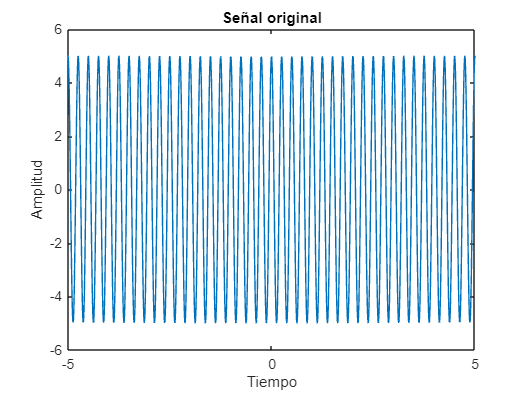

%varia escalamiento
clc; close all; clear;  
% Definir la señal de entrada
L=1000;
t = linspace(-5, 5, L);
A=5; %amplitud
f0=4; %frecuencia en Hz
w_0=2*pi*f0;
x = A*cos(w_0.*t);
figure(1)
plot(t,x);
title('Señal original');
xlabel('Tiempo');
ylabel('Amplitud');
axis([-5 5 -A-1 A+1])

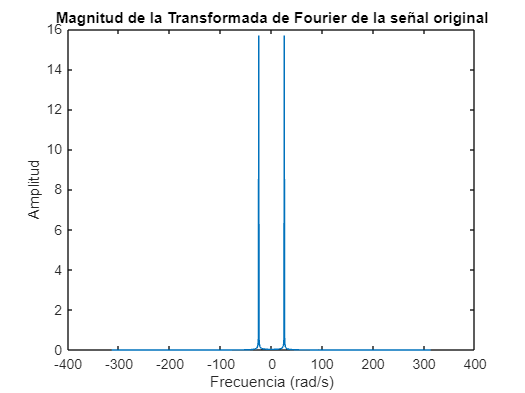


% Calcular la Transformada de Fourier de la señal
X = fftshift(fft(x));
Fs=1/(t(2)-t(1)); %frecuencia de muestreo
f=(-L/2:L/2-1)*Fs/L; %Frecuencia normalizada en rad/muestra

%Ploteamos la magnitud y fase de la transformada de fourier
figure(2)
plot(2*pi*f, 2*pi*abs(X)/L);
title('Magnitud de la Transformada de Fourier de la señal original');
xlabel('Frecuencia (rad/s)');
ylabel('Amplitud');

Código 2.9 Gráfico de Función Coseno

####  Actividad: **Transformada de Fourier del seno (Propiedad 33)**


$$\sin(\omega_0t) \leftrightarrow -j\pi\left[\delta(\omega-\omega_0)+\delta(\omega+\omega_0)\right]$$


%varia escalamiento 
clc; close all; clear;
% Definir la señal de entrada
L=1000;
t = linspace(-5, 5, L);
A=5; %amplitud
f0=4; %frecuencia en Hz
w_0=2*pi*f0;
x = A*cos(w_0.*t);
figure(3)
plot(t,x);
title('Señal original');
xlabel('Tiempo');
ylabel('Amplitud');
axis([-5 5 -A-1 A+1])

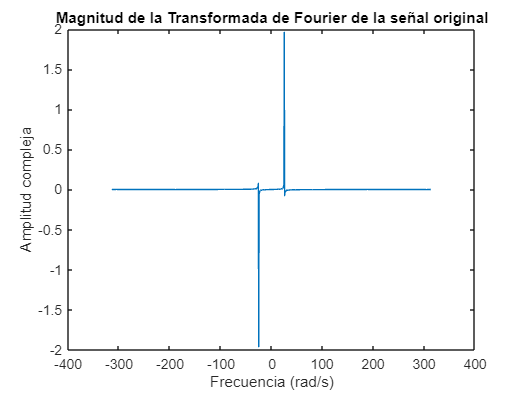



% Calcular la Transformada de Fourier de la señal
X = fftshift(fft(x));
Fs=1/(t(2)-t(1)); %frecuencia de muestreo
f=(-L/2:L/2-1)*Fs/L; %Frecuencia normalizada en rad/muestra

%Ploteamos la magnitud y fase de la transformada de fourier
figure(4)
plot(2*pi*f, 2*pi*imag(X)/L);
title('Magnitud de la Transformada de Fourier de la señal original');
xlabel('Frecuencia (rad/s)');
ylabel('Amplitud compleja');

Código 2.10 Gráfico de Función Seno

####  Actividad: **Sumando el coseno y el seno en el Dominio del tiempo y de la frecuencia **


$$f\left(t\right)=\cos \left(2\pi \cdot 15t-\frac{\pi }{4}\right)-\sin \left(2\pi \cdot 40t\right)$$


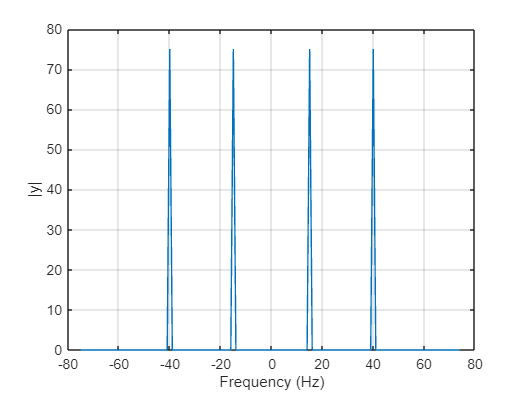

clear all;
close all;
clc;
fs = 150;
t = 0:1/fs:1-1/fs;
x = cos(2*pi*15*t - pi/4) - sin(2*pi*40*t);

y = fft(x);
z = fftshift(y);

ly = length(y);
f = (-ly/2:ly/2-1)/ly*fs;

plot(f,abs(z))
xlabel("Frequency (Hz)")
ylabel("|y|")
grid

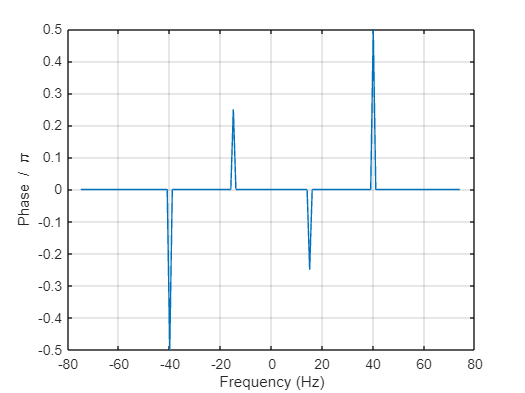


tol = 1e-6;
z(abs(z) < tol) = 0;

theta = angle(z);

plot(f,theta/pi)
xlabel("Frequency (Hz)")
ylabel("Phase / \pi")
grid

Código 2.11 Gráfico de Función Coseno + Seno

####  Actividad: **Propiedad de modulación utilizando una señal cosenoidal como portadora (Propiedad 6)**


$$f(t)\cos \omega_0t	\leftrightarrow  \frac{1}{2}F(\omega-\omega_0)+\frac{1}{2}F(\omega+\omega_0)
$$


Para los ejemplos de modulación, consideraremos como f(t) al pulso rectangular de ancho de banda a=3

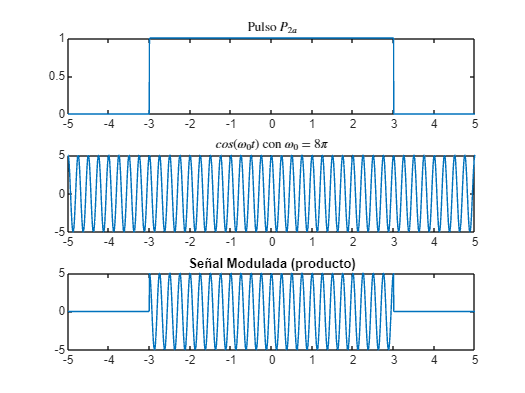

clc; close all; clear;
% Definir la señal de entrada
t = linspace(-5, 5, 2000);
A=5; %amplitud
f=4; %frecuencia en Hz
w_0=2*pi*f;
cos_vector = A*cos(w_0.*t);
P_2a=heaviside(t+3)-heaviside(t-3);
%Realizamos la modulación:
x=P_2a.*cos_vector;
%Ploteamos en el dominio del tiempo
figure,
subplot(3,1,1);
plot(t,P_2a);
title("Pulso $P_{2a}$",'Interpreter','LaTeX')
subplot(3,1,2);
plot(t,cos_vector);
title("$cos(\omega_0 t)$ con $\omega_0=8\pi$",'Interpreter','LaTeX')
subplot(3,1,3);
plot(t,x);
title("Señal Modulada (producto)")

Ahora, obtenemos la transformada de Fourier de cada una de las señales y las ploteamos en el dominio de la frecuencia para observar el resultado:

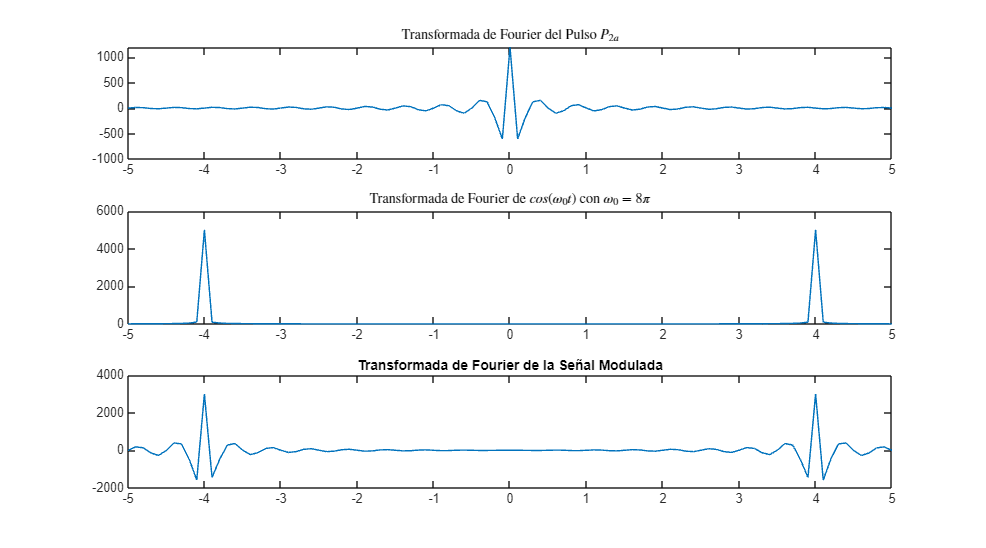


Fs=200; %frecuencia de muestreo
[w_Hz,FFT_pulso]=FFT_custom(P_2a,Fs);
[~,FFT_cos]=FFT_custom(cos_vector,Fs);
[~,FFT_x]=FFT_custom(x,Fs);
w=w_Hz*2*pi/Fs; %Frecuencia normalizada en rad/muestra
%Ploteamos en el dominio de la frecuencia
figure('Position',[140,420,1800,1000]);
subplot(3,1,1);
plot(w_Hz,real(FFT_pulso));
title("Transformada de Fourier del Pulso $P_{2a}$",'Interpreter','LaTeX')
xlim([-5 5])
subplot(3,1,2);
plot(w_Hz,abs(FFT_cos));
xlim([-5 5])
title("Transformada de Fourier de $cos(\omega_0 t)$ con $\omega_0=8\pi$",'Interpreter','LaTeX')
subplot(3,1,3);
plot(w_Hz,real(FFT_x));
xlim([-5 5])
title("Transformada de Fourier de la Señal Modulada")

Código 2.12 Gráfico de Función Coseno multiplicado por Pulso

####  Actividad: **Propiedad de modulación utilizando una señal senoidal como portadora (Propiedad 7)**


$$f(t)\sin \omega_0t \leftrightarrow  \frac{1}{2j}F(\omega-\omega_0)-\frac{1}{2j}F(\omega+\omega_0)$$


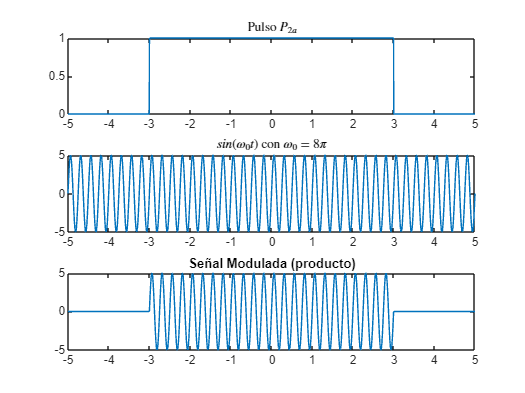

clc; close all; clear;
% Definir la señal de entrada
t = linspace(-5, 5, 2000);
A=5; %amplitud
f=4; %frecuencia en Hz
w_0=2*pi*f;
sin_vector = A*sin(w_0.*t);
P_2a=heaviside(t+3)-heaviside(t-3);
%Realizamos la modulación:
x=P_2a.*sin_vector;
%Ploteamos en el dominio del tiempo
figure,
subplot(3,1,1);
plot(t,P_2a);
title("Pulso $P_{2a}$",'Interpreter','LaTeX')
subplot(3,1,2);
plot(t,sin_vector);
title("$sin(\omega_0 t)$ con $\omega_0=8\pi$",'Interpreter','LaTeX')
subplot(3,1,3);
plot(t,x);
title("Señal Modulada (producto)")

Ahora, obtenemos la transformada de Fourier de cada una de las señales y las ploteamos en el dominio de la frecuencia para observar el resultado:

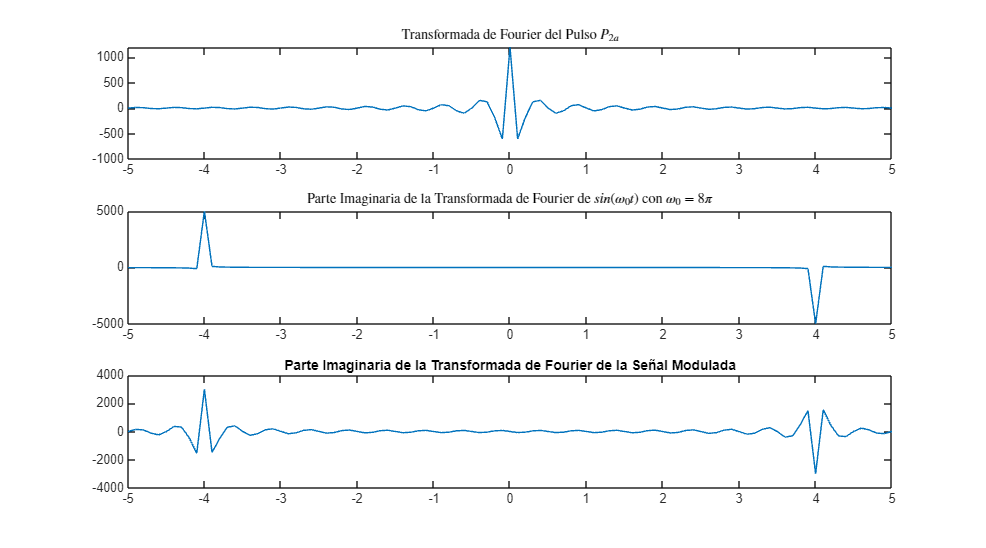

Fs=200; %frecuencia de muestreo
[w_Hz,FFT_pulso]=FFT_custom(P_2a,Fs);
[~,FFT_sin]=FFT_custom(sin_vector,Fs);
[~,FFT_x]=FFT_custom(x,Fs);
w=w_Hz*2*pi/Fs; %Frecuencia normalizada en rad/muestra
%Ploteamos en el dominio de la frecuencia
figure('Position',[140,420,1800,1000]);
subplot(3,1,1);
plot(w_Hz,real(FFT_pulso));
title("Transformada de Fourier del Pulso $P_{2a}$",'Interpreter','LaTeX')
xlim([-5 5])
subplot(3,1,2);
plot(w_Hz,imag(FFT_sin));
xlim([-5 5])
title("Parte Imaginaria de la Transformada de Fourier de $sin(\omega_0 t)$ con $\omega_0=8\pi$",'Interpreter','LaTeX')
subplot(3,1,3);
plot(w_Hz,imag(FFT_x));
xlim([-5 5])
title("Parte Imaginaria de la Transformada de Fourier de la Señal Modulada")

Código 2.13 Gráfico de Función Seno multiplicado por Pulso

####  Actividad: **Transformada de Fourier de una señal exponencial decreciente (Propiedad 17)**


$$e^{-at}u(t) \leftrightarrow\frac{1}{j\omega + a}$$


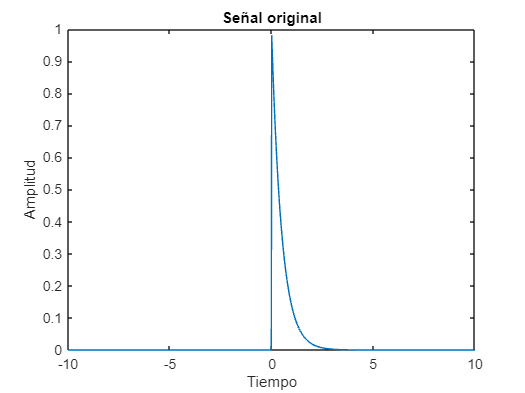

clc; close all; clear;
% Definir la señal de entrada
t = linspace(-10, 10, 1000);
a=2;
x = exp(-1*a.*t).*heaviside(t);
figure,
plot(t,x);
title('Señal original');
xlabel('Tiempo');
ylabel('Amplitud');

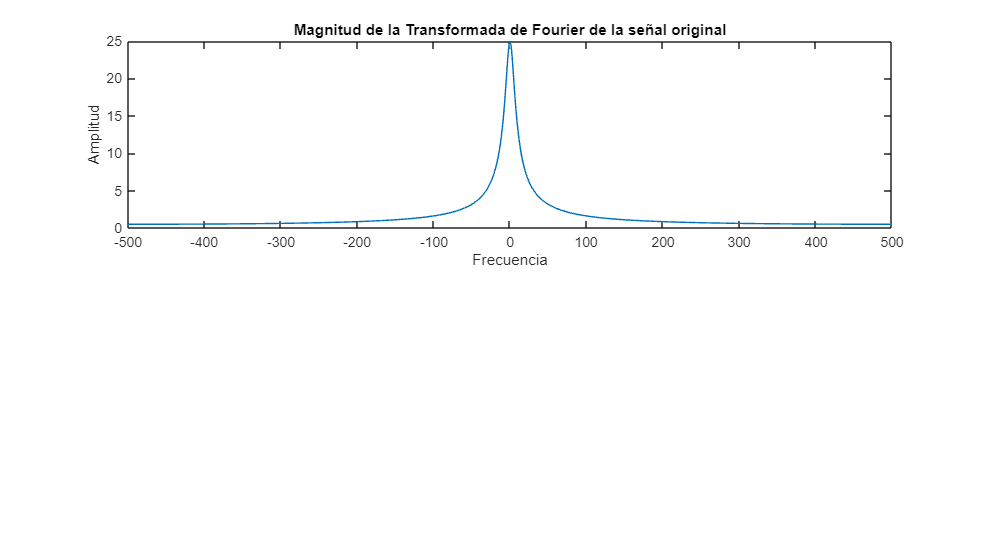


Fs=1000; %frecuencia de muestreo

% Calcular la Transformada de Fourier de la señal
[w_Hz,X] = FFT_custom(x,Fs);
w=w_Hz*2*pi/Fs; %Frecuencia normalizada en rad/muestra

%Ploteamos la magntiud de la transformada de fourier
figure('Position',[140,420,1800,1000]);
subplot(2,1,1);
plot(w_Hz, abs(X));
title('Magnitud de la Transformada de Fourier de la señal original');
xlabel('Frecuencia');
ylabel('Amplitud');

Código 2.14 Gráfico de la Función Exponencial

Estas propiedades nos dejan algunas preguntas que son muy importantes.Pero a la vez algunas observaciones que podemos desprender de lo visto previamente, por ejemplo: es una hecho que la mayor parte de la potencia de una señal puede estar almacenada en unas pocas componentes.

** Preguntan 15. **Para recordar lo visto previo a las propiedades, ¿Cuáles son las características de las señales con las que vamos a trabajar? ¿Cómo deberíamos graficarlas en el dominio del tiempo y de la frecuencia? ¿En qué sirve que la mayor parte de la potencia de una señal quede almacenada en unas pocas componentes?

## Bibliografía:

- [*Análisis de Fourier*](https://pucp.ent.sirsi.net/client/es_ES/campus/search/detailnonmodal/ent:$002f$002fSD_ILS$002f0$002fSD_ILS:430979/one)*, *HWEI P. HSU, 1ra. Edición Addison-Wesley  (1998). Este debe ser tu primer libro a revisar, pues aquí encontrarás toda la base matemática expuesta en esta unidad y más aún. Ojo que aquí se demuestran y grafican muchas de las propiedades.

- [*Modern digital and analog Communication Systems*](https://pucp.ent.sirsi.net/client/es_ES/campus/search/detailnonmodal/ent:$002f$002fSD_ILS$002f0$002fSD_ILS:518634/one)*, B. P. LATHI, 3rd Edition Oxford University Press (1998).*

- [*Introducción a los Sistemas de Comunicación*](https://pucp.ent.sirsi.net/client/es_ES/campus/search/detailnonmodal/ent:$002f$002fSD_ILS$002f0$002fSD_ILS:62302/one)*,  F.G. STREMLER, 3ra. Edición Addison-Wesley  (1993).*

Estos 3 libros con una sólida pero corta teoría del análisis de Fourier están orientados a la aplicación de la teoría de Fourier, muy recomendables para aprender desde la convolución hasta los sistemas lineales, criterios de realizabilidad física, etc. 

## Funciones Locales Usadas en este Script

#### Actividad. Transformada Rápida de Fourier, con eje de frecuencia normalizada reconstruído a Hz

function [w_Hz,FFT]=FFT_custom(y,Fs)
    FFT= fftshift(fft(y)); %rango fundamental simétrico de -pi a pi
    k= 0:length(FFT)-1;
    w=2*pi*k/length(FFT);
    w=unwrap(fftshift(w))-2*pi; %eje de frecuencias normalizadas, en rad/muestra
    w_Hz=w*Fs/(2*pi); %eje de frecuencia normalizada reconstruído a Hz
    %se necesita como parámetro de entrada la frecuencia de muestreo
end
